clearvars

## Find the SNR SNDR

clearvars
folderPath = 'C:\Users\steve\OneDrive\Documents\GitHub\ECE266_CMOSCircuitLab\Lab6_EvalADC\Data';  % Specify the folder path
pattern = 'output-freq-*.bin';    % Define the file name pattern
% Get a list of files matching the pattern
files = dir(fullfile(folderPath, pattern));
files_name = strings(length(files), 1);
frequencies1 = zeros(1,length(files));
for i = 1:length(files)
    temp = files(i).name;
    files_name(i) = convertCharsToStrings(temp);
end
for k = 1:length(files)
    % Get the full path of the file
    filePath = fullfile(folderPath, files(k).name);
    
    % Extract frequency from the file name
    matches = regexp(files(k).name, 'output-freq-([\d.]+)', 'tokens');
    if ~isempty(matches)
        frequency = string(matches);
        frequency = regexprep(frequency, '(?<=\d+\.\d*)\.', '');
        frequencies1(1,k) = str2double(frequency);
        
    else
        disp('Frequency not found.');
    end
end
Data_filt = zeros(262144,length(frequencies1));
for i = 1:length(frequencies1)
    file_path = strcat("C:\Users\steve\OneDrive\Documents\GitHub\ECE266_CMOSCircuitLab\Lab6_EvalADC\Data\", files_name(i,1));
    fileID = fopen(file_path);
    bin_data = fread(fileID,'uint16');
    
    % Remove the zeros
    filtered_data = bin_data(bin_data ~= 0);
    filtered_data =filtered_data';
    Data_filt(:,i) = bin_data(1:4:end);
end
Set = zeros(3,length(frequencies1));
Fs=1e6;
num_segments=1;
f_s = Fs;
BW =500e3;
sample_size=2^18;
periodogram_length = sample_size / num_segments;
fbin = f_s / periodogram_length;
plotYN = 0; plotAll = 0; plotHold = 0; plotLin = 0; datNorm = 1;
for i = 1: length(frequencies1)
    f_signal = frequencies1(1,i);
    [sinusoid_power, data_minus_sinusoid_in_BW_power, SNDR, ENOB,HD2,HD3, SNR, SFDR] = ...
    plot_periodogram_SFDR(Data_filt(:,i), periodogram_length, num_segments, f_signal, ...
    f_s, BW, plotAll, plotHold, plotYN, plotLin,datNorm);
    % fprintf('@Freq = %.3f, SNR = %.3f dB, SNDR = %.3f dB, SFDR = %.3f dB, HD2 = %.3f and HD3 = %.3f\n',   f_signal, SNR,SNDR, SFDR, HD2,HD3);
    Set(1,i) = f_signal;
    Set(2,i) = SNR;
    Set(3,i) = SNDR;
end
% Sort the array
[~, idx] = sort(Set(1, :)); 
Set = Set(:, idx); 
save('Set.mat', 'Set');

## Plot SNR And SNDR from 0.1k to 250kHz

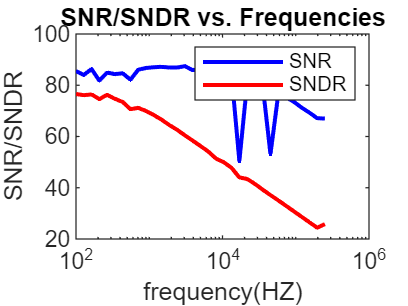

load('Set.mat')
figure
semilogx(Set(1,:), Set(2,:), 'b-', 'LineWidth', 1.5,"DisplayName","SNR");
hold on
semilogx(Set(1,:), Set(3,:), 'r-', 'LineWidth', 1.5, "DisplayName","SNDR");
hold off
xlabel("frequency(HZ)"); ylabel("SNR/SNDR");
title("SNR/SNDR vs. Frequencies");
legend;

## Find SFDR

clearvars
folderPath = 'C:\Chengming_Li\GitHub\ECE266_CMOSCircuitLab\Lab6_EvalADC\Data2';  % Specify the folder path
pattern = 'output-freq-*.bin';    % Define the file name pattern
% Get a list of files matching the pattern
files = dir(fullfile(folderPath, pattern));
files_name = strings(length(files), 1);
frequencies2 = zeros(1,length(files));
for i = 1:length(files)
    temp = files(i).name;
    files_name(i) = convertCharsToStrings(temp);
end
for k = 1:length(files)
    % Get the full path of the file
    filePath = fullfile(folderPath, files(k).name);
    % Extract frequency from the file name
    matches = regexp(files(k).name, 'output-freq-([\d.]+)', 'tokens');
    if ~isempty(matches)
        frequency = string(matches);
        frequency = regexprep(frequency, '(?<=\d+\.\d*)\.', '');
        frequencies2(1,k) = str2double(frequency);
    else
        disp('Frequency not found.');
    end
end
Data_filt = zeros(262144,length(frequencies2));
for i = 1:length(frequencies2)
    file_path = strcat("C:\Chengming_Li\GitHub\ECE266_CMOSCircuitLab\Lab6_EvalADC\Data2\", files_name(i,1));
    fileID = fopen(file_path);
    bin_data = fread(fileID,'uint16');
    freq = frequencies2(1,i);
    
    % Remove the zeros
    filtered_data = bin_data(bin_data ~= 0);
    filtered_data =filtered_data';
    Data_filt(:,i) = bin_data(1:4:end);
end
Set2 = zeros(2,length(frequencies2));
Fs=1e6;
num_segments=1;
f_s = Fs;
BW =500e3;
sample_size=2^18;
periodogram_length = sample_size / num_segments;
fbin = f_s / periodogram_length;
plotYN = 0; plotAll = 0; plotHold = 0; plotLin = 0; datNorm = 1;
for i = 1: length(frequencies2)
    f_signal = frequencies2(1,i);
    [sinusoid_power, data_minus_sinusoid_in_BW_power, SNDR, ENOB,HD2,HD3, SNR, SFDR] = ...
    plot_periodogram_SFDR(Data_filt(:,i), periodogram_length, num_segments, f_signal, ...
    f_s, BW, plotAll, plotHold, plotYN, plotLin,datNorm);
    % fprintf('@Freq = %.3f, SNR = %.3f dB, SNDR = %.3f dB, SFDR = %.3f dB, HD2 = %.3f and HD3 = %.3f\n',   f_signal, SNR,SNDR, SFDR, HD2,HD3);
    Set2(1,i) = f_signal;
    Set2(2,i) = SFDR;
end
% Sort the array
[~, idx] = sort(Set2(1, :)); 
Set2 = Set2(:, idx); 
save('Set2.mat', 'Set2');


## Plot SFDR from 0.1k to 20kHz

load('Set2.mat')
figure
semilogx(Set2(1,:), Set2(2,:), 'b-', 'LineWidth', 1.5,"DisplayName","SFDR");

xlabel("frequency(HZ)"); ylabel("SFDR");
title("SFDR vs. Frequencies");
legend;